# Spectrum Sensing Based on Autocorrelation of Samples With K-Means

## Loading the data

First of all, let's load the datasets. We have 13 datasets, all taken from signal from the air. 

We have 10 datasets with radio signal data (5 taken from FM 93.9 and 5 from FM 88.9) and 3 data without signal (taken from a frequency that has no transmitting signal);

For train the *k*-Means Clustering Algorithm we'll gonna use a dataset with signal (sampled from FM 88.9) and a dataset with noise (sample without signal taken from the air).

clc; clear;
SizeSampled = 4000000 %Normalize size sample. The size in complex is SizeSampled/2;

SizeSampled = 4000000


%In this example we gonna use 8 of these 13 dataset. 

%You can change the data using to traning, to do this change the number 
% in FM88_(1, 2, 3, 4 or 5).dat and NoSignal_(1, 2 or 3).dat. 

%You can also chance from FM88 to FM93 using FM93_(1, 2, 3, 4 or 5).dat 
%(Don't use two data with signal for tranning!)

%THE FM93_1.dat and NoSignal_3.dat NEEDS A SMALLER SIZESAMPLED (Use
%2000000 if you want to use those data and change the KmeansSamples to 10
%if you want the same batch size).

%Traning Data
a = fopen("data\FM88_1.dat");
b = fopen("data\NoSignal_1.dat");

%Loading data from FM 88.9 as complex.
valuesFM88 = fread(a, SizeSampled, 'float');
complexValues_FM88 = valuesFM88(1:2:end,:) + valuesFM88(2:2:end,:)*i

complexValues_FM88 =   -0.0001 + 0.0002i
   0.0006 + 0.0066i
   0.0006 + 0.0012i
   0.0042 + 0.0012i
   0.0009 - 0.0029i
   0.0028 - 0.0031i
   0.0044 - 0.0031i
   0.0004 - 0.0031i
   0.0004 - 0.0031i
   0.0004 - 0.0031i



%Loading data with noise as complex.
valuesNoise = fread(b, SizeSampled, 'float');
complexValues_Noise = valuesNoise(1:2:end,:) + valuesNoise(2:2:end,:)*i

complexValues_Noise =   -0.0001 - 0.0001i
  -0.0012 + 0.0042i
  -0.0029 - 0.0010i
   0.0028 + 0.0025i
   0.0025 - 0.0031i
   0.0004 - 0.0012i
   0.0023 - 0.0031i
  -0.0031 + 0.0025i
   0.0007 - 0.0007i
   0.0025 + 0.0007i



%Cleaning5
fclose('all');
clear a b c valuesFM88 valuesNoise;

## Plot of the autocorrelation of the data

Autocorrelation of signal from FM 88.9:

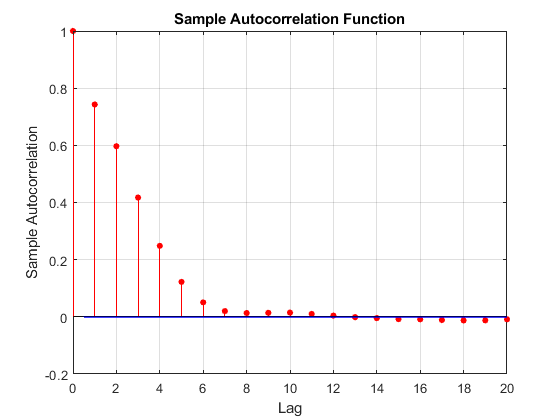

autocorr(complexValues_FM88)

Autocorrelation of the noise:

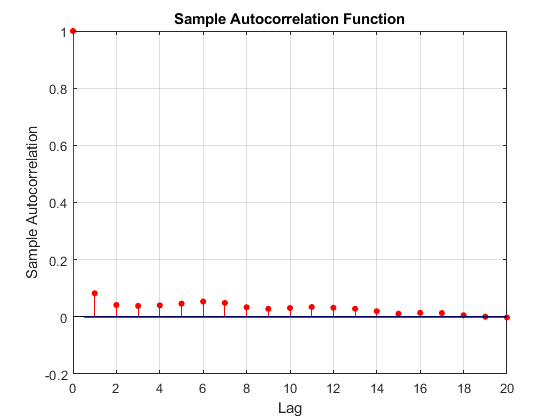

autocorr(complexValues_Noise)

## Calculating the autocorrelation

#### Spliting the data into minor samples

We'll split the data sample into '*KmeansSamples' *batches with sample size '(*SizeSampled/2)/KmeansSamples'  each.**

*(*We are using 20 batches with sample size = 1e5) *

KmeansSamples = 20 %Split the data to make N samples for Kmeans 

KmeansSamples = 20

%Spliting the data
fm88Data = reshape(complexValues_FM88, [],  KmeansSamples)

fm88Data =   -0.0001 + 0.0002i   0.0009 - 0.0031i  -0.0031 + 0.0025i   0.0042 + 0.0009i  -0.0031 - 0.0031i  -0.0031 - 0.0029i   0.0023 - 0.0031i   0.0047 + 0.0009i  -0.0012 + 0.0047i   0.0028 - 0.0010i   0.0047 + 0.0004i   0.0023 + 0.0047i  -0.0047 - 0.0031i  -0.0012 + 0.0042i  -0.0031 - 0.0031i  -0.0029 + 0.0047i   0.0028 + 0.0028i  -0.0031 - 0.0031i  -0.0031 + 0.0006i  -0.0031 + 0.0012i
   0.0006 + 0.0066i   0.0012 - 0.0029i  -0.0050 - 0.0012i   0.0044 + 0.0009i  -0.0031 - 0.0012i  -0.0031 - 0.0031i   0.0007 - 0.0031i   0.0047 - 0.0029i   0.0007 + 0.0047i   0.0047 + 0.0012i   0.0047 + 0.0004i   0.0063 + 0.0047i  -0.0026 - 0.0031i  -0.0031 + 0.0042i  -0.0031 + 0.0004i   0.0009 + 0.0047i  -0.0007 + 0.0028i  -0.0031 - 0.0012i  -0.0031 - 0.0031i  -0.0031 + 0.0012i
   0.0006 + 0.0012i   0.0012 - 0.0026i  -0.0031 + 0.0042i   0.0047 - 0.0026i  -0.0031 - 0.0012i  -0.0031 - 0.0031i  -0.0029 - 0.0034i   0.0047 - 0.0031i   0.0012 + 0.0047i   0.0012 + 0.0012i   0.0028 - 0.0031i   0.0044 + 0.0025

noiseData = reshape(complexValues_Noise, [],  KmeansSamples)

noiseData =   -0.0001 - 0.0001i   0.0004 + 0.0009i  -0.0010 - 0.0012i  -0.0026 - 0.0010i   0.0004 + 0.0004i   0.0025 + 0.0004i   0.0004 - 0.0012i   0.0004 - 0.0007i   0.0004 - 0.0031i   0.0023 - 0.0012i   0.0004 - 0.0012i  -0.0012 - 0.0012i  -0.0031 - 0.0012i  -0.0010 - 0.0010i  -0.0029 - 0.0012i  -0.0029 - 0.0029i   0.0004 - 0.0026i  -0.0031 - 0.0007i  -0.0010 - 0.0010i  -0.0031 + 0.0009i
  -0.0012 + 0.0042i  -0.0012 - 0.0007i  -0.0012 + 0.0007i  -0.0026 - 0.0026i   0.0007 - 0.0031i  -0.0012 + 0.0004i   0.0004 - 0.0012i  -0.0012 - 0.0029i  -0.0010 - 0.0031i  -0.0010 - 0.0031i   0.0004 - 0.0012i  -0.0029 - 0.0029i  -0.0029 - 0.0010i  -0.0007 + 0.0042i  -0.0031 + 0.0023i  -0.0031 + 0.0025i  -0.0012 + 0.0007i  -0.0029 + 0.0025i   0.0042 - 0.0029i  -0.0031 - 0.0010i
  -0.0029 - 0.0010i  -0.0031 - 0.0010i  -0.0029 - 0.0007i  -0.0029 - 0.0007i  -0.0007 - 0.0012i   0.0004 + 0.0006i  -0.0012 - 0.0012i  -0.0012 - 0.0031i  -0.0010 - 0.0031i  -0.0007 + 0.0023i  -0.0031 - 0.0031i   0.0009 - 0.002

#### Calculating the autocorrelations of the N samples from each dataset.

Here we're calculating the autocorrelation of each one of the batches in each dataset with the function autocorr().

%Autocorrelations of the N samples from each data
NumLags = 20;
acfFM88 = zeros(NumLags+1,KmeansSamples); %Preallocating matrix for code speed
acfNoise = zeros(NumLags+1,KmeansSamples);  %Preallocating matrix for code speed
for i = 1:KmeansSamples
[acfFM88(:,i)] = autocorr(fm88Data(:,i), NumLags); %autocorrelation of signal FM 88.9 
[acfNoise(:,i), lags] = autocorr(noiseData(:,i), NumLags); %autocorrelation of the noise
end

## Plot of the autocorrelation of the splitted datas

Example of autocorrelation of the signal from FM 88.9 from the splitted data: 

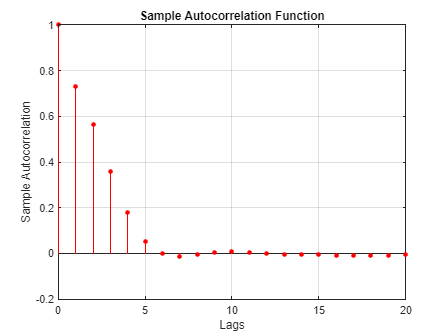

stem(lags, acfFM88(:,1), 'r.', 'MarkerSize', 13)
xlabel('Lags');
ylabel('Sample Autocorrelation');
title('Sample Autocorrelation Function');
grid on;

Example of autocorrelation of the noise from splitted data:

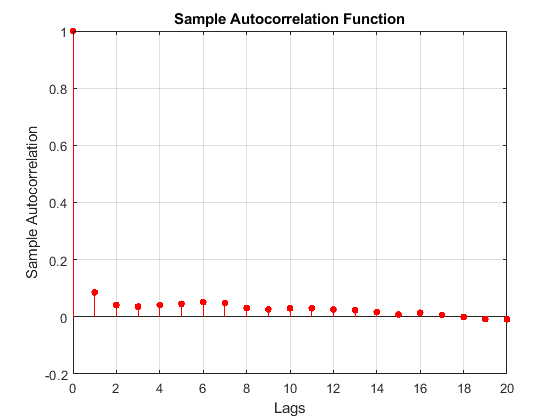

stem(lags, acfNoise(:,1), 'r.', 'MarkerSize', 13)
xlabel('Lags');
ylabel('Sample Autocorrelation');
title('Sample Autocorrelation Function');
grid on;

## Mean and Variance of the samples autocorrelation 

#### **Signal FM 88.9**

meansFM88 = mean(acfFM88)

meansFM88 =     0.1351    0.1427    0.1453    0.1373    0.1358    0.1341    0.1381    0.1390    0.1629    0.1391    0.1618    0.1565    0.1415    0.1721    0.2309    0.1398    0.1643    0.1732    0.1413    0.1434


varFM88 = var(acfFM88)

varFM88 =     0.0814    0.0828    0.0802    0.0796    0.0818    0.0820    0.0826    0.0849    0.0832    0.0882    0.0857    0.0847    0.0905    0.0844    0.0874    0.0897    0.0830    0.0849    0.0882    0.0906


#### **Noise**

meansNoise = mean(acfNoise)

meansNoise =     0.0735    0.0711    0.0702    0.0741    0.0738    0.0769    0.0757    0.0752    0.0775    0.0780    0.0758    0.0751    0.0752    0.0777    0.0802    0.0790    0.0778    0.0794    0.0762    0.0805


varNoise = var(acfNoise)

varNoise =     0.0455    0.0458    0.0459    0.0455    0.0455    0.0451    0.0452    0.0454    0.0451    0.0450    0.0452    0.0453    0.0453    0.0450    0.0447    0.0448    0.0450    0.0448    0.0452    0.0447


### Plot the Autocorrelation Mean vs Autocorrelation Variance

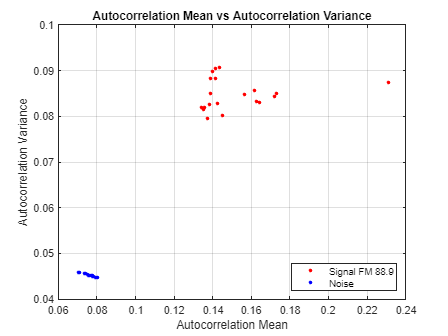



plot(meansFM88(:), varFM88(:), 'r.','Markersize', 10); %Plot FM 88.9
hold on;
plot(meansNoise(:), varNoise(:), 'b.', 'Markersize', 10); %Plot Noise
hold off;
grid on;

%labels and legends
title('Autocorrelation Mean vs Autocorrelation Variance');
xlabel('Autocorrelation Mean');
ylabel('Autocorrelation Variance');
legend('Signal FM 88.9 ', 'Noise', Location='southeast');

## ***k-*****Means **

We are gonna join the means and variances of the signal and noise into a matrix *X* to clusterer the data with k-means. 

X = [meansFM88  meansNoise ; varFM88 varNoise];
X = X.'

X =     0.1351    0.0814
    0.1427    0.0828
    0.1453    0.0802
    0.1373    0.0796
    0.1358    0.0818
    0.1341    0.0820
    0.1381    0.0826
    0.1390    0.0849
    0.1629    0.0832
    0.1391    0.0882


#### **K-means clustering:**

We gonna create two clusters and expect them to separate the signal data from noise data. 

[idx, C] = kmeans(X, 2, 'Start', [0, 0; 1,1]);  
%(*We use initial centroids in (0,0) and (1,1) but that is not really necessary)


#### **Plot with clusters centroids:**

Now we are adding the centroids to the previous graph, and we can see that each one are close to one type of data (with and without signal).

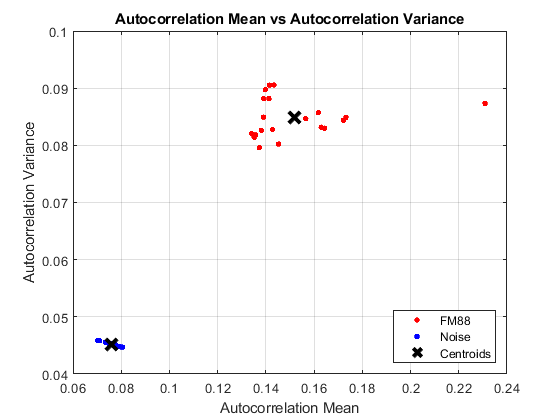

hold on;
plot(C(:,1),C(:,2),'kx','MarkerSize',12, 'LineWidth', 3);
legend('FM88 ', 'Noise', 'Centroids', Location='southeast');
hold off;

## Plot the clusters and the cluster centroids.

Now that we've created the centroids, let's see how each of the samples is clustered.

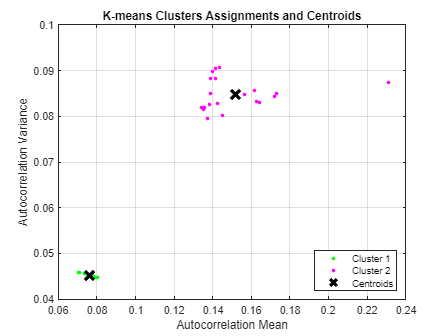

plot(X(idx==1,1),X(idx==1,2),'g.','MarkerSize',10);
hold on
plot(X(idx==2,1),X(idx==2,2),'m.','MarkerSize',10);
plot(C(:,1),C(:,2),'kx',...
    'MarkerSize',12,'LineWidth',3) ;

title('K-means Clusters Assignments and Centroids');
xlabel('Autocorrelation Mean');
ylabel('Autocorrelation Variance');
legend('Cluster 1', 'Cluster 2', 'Centroids', Location='southeast');

grid on
hold off

In this classification we grant the correct separation of the data within the two clusters. This is the result we expect, but now we need to adding more data samples and verify that they'll be classified correctly.

## Generate a test data set.

Now that we have encontered the centroids with *k*-Means, we can assing new data to existing clusters. For that, new data must be generate, and we gonna use 5 of the datasets sampled from the air, different from those we use for training.

We're using two sampled datasets from FM 93.9, two from FM 88.9 and one of noise (no signal).

clearvars -except C 
%Cleaning all variables except the clusters Centroids 
% (because for some reason the new complex data loaded will be real after calculating the autocorrelation of the split data). 
% Only the centroids are needed for assing new data to the clusters

%You can also change test data in the same way as tranning data

SizeSampled = 4000000

SizeSampled = 4000000

%New data for test 
a = fopen("data\FM88_4.dat");
b = fopen("data\FM88_5.dat");
c = fopen("data\FM93_4.dat");
d = fopen("data\FM93_5.dat");
e = fopen("data\NoSignal_2.dat");

%Loading data from FM 88.9 as complex.
valuesFM88_test1 = fread(a, SizeSampled, 'float');
complexValues_FM88_test1 = valuesFM88_test1(1:2:end,:) + valuesFM88_test1(2:2:end,:)*i

complexValues_FM88_test1 =    0.0002 - 0.0001i
   0.0007 - 0.0031i
  -0.0031 - 0.0031i
  -0.0031 - 0.0012i
  -0.0012 + 0.0006i
  -0.0031 - 0.0010i
  -0.0031 + 0.0047i
  -0.0050 + 0.0047i
  -0.0031 + 0.0028i
  -0.0029 + 0.0047i



%Loading data from FM 88.9 as complex.
valuesFM88_test2 = fread(b, SizeSampled, 'float');
complexValues_FM88_test2 = valuesFM88_test2(1:2:end,:) + valuesFM88_test2(2:2:end,:)*i

complexValues_FM88_test2 =   -0.0001 + 0.0002i
  -0.0047 - 0.0007i
  -0.0029 + 0.0009i
   0.0007 + 0.0028i
   0.0028 + 0.0047i
   0.0047 + 0.0028i
   0.0047 + 0.0009i
  -0.0007 - 0.0031i
   0.0009 - 0.0031i
  -0.0012 - 0.0031i



%Loading data from FM 93.9 as complex.
valuesFM93_test1 = fread(c, SizeSampled, 'float');
complexValues_FM93_test1 = valuesFM93_test1(1:2:end,:) + valuesFM93_test1(2:2:end,:)*i

complexValues_FM93_test1 =   -0.0001 - 0.0001i
  -0.0031 - 0.0031i
  -0.0031 - 0.0012i
  -0.0031 + 0.0025i
  -0.0031 - 0.0007i
  -0.0031 + 0.0025i
  -0.0031 + 0.0044i
  -0.0031 - 0.0007i
   0.0004 + 0.0012i
  -0.0031 + 0.0012i



valuesFM93_test2 = fread(d, SizeSampled, 'float');
complexValues_FM93_test2 = valuesFM93_test2(1:2:end,:) + valuesFM93_test2(2:2:end,:)*i

complexValues_FM93_test2 =    0.0002 + 0.0002i
   0.0047 + 0.0047i
  -0.0010 + 0.0028i
  -0.0031 + 0.0025i
  -0.0031 + 0.0042i
  -0.0031 + 0.0004i
  -0.0031 - 0.0031i
  -0.0031 - 0.0031i
  -0.0010 - 0.0031i
  -0.0007 - 0.0031i



%Loading data with noise as complex.
valuesNoise_test = fread(e, SizeSampled, 'float');
complexValues_Noise_test = valuesNoise_test(1:2:end,:) + valuesNoise_test(2:2:end,:)*i

complexValues_Noise_test =   -0.0001 + 0.0002i
   0.0044 - 0.0029i
   0.0025 + 0.0023i
   0.0004 - 0.0031i
   0.0023 - 0.0031i
  -0.0031 - 0.0029i
   0.0042 - 0.0029i
  -0.0031 - 0.0012i
   0.0004 - 0.0012i
  -0.0010 - 0.0012i



%Cleaning
fclose('all');
clear a b c d e valuesFM88_test1 valuesFM88_test2...
    valuesFM93_test1 valuesFM93_test2 valuesNoise_test;

**We're splitting each of the data into 20 batches of 1e5 as we did in the tranning*

KmeansSamplesTest = 20 %Split the data to make N samples for Kmeans 

KmeansSamplesTest = 20



%Spliting the data
fm88DataTest1 = reshape(complexValues_FM88_test1, [],  KmeansSamplesTest)

fm88DataTest1 =    0.0002 - 0.0001i  -0.0031 - 0.0031i   0.0028 + 0.0047i  -0.0034 + 0.0047i   0.0044 + 0.0028i  -0.0031 - 0.0010i  -0.0031 + 0.0007i   0.0023 + 0.0025i  -0.0031 + 0.0009i   0.0047 - 0.0031i   0.0047 - 0.0029i   0.0047 - 0.0026i  -0.0048 + 0.0004i   0.0009 - 0.0031i  -0.0034 - 0.0031i  -0.0029 - 0.0031i   0.0025 - 0.0031i  -0.0031 - 0.0031i   0.0023 + 0.0047i  -0.0031 - 0.0031i
   0.0007 - 0.0031i  -0.0050 - 0.0010i   0.0028 + 0.0044i   0.0001 + 0.0047i   0.0009 + 0.0009i  -0.0031 + 0.0025i  -0.0031 + 0.0009i   0.0004 + 0.0044i   0.0007 + 0.0047i   0.0028 - 0.0012i   0.0009 + 0.0044i   0.0009 - 0.0029i  -0.0031 - 0.0031i   0.0047 + 0.0006i  -0.0031 - 0.0031i   0.0009 - 0.0031i   0.0006 - 0.0031i  -0.0031 - 0.0031i   0.0007 + 0.0028i  -0.0031 - 0.0031i
  -0.0031 - 0.0031i  -0.0031 + 0.0012i   0.0047 + 0.0042i   0.0023 + 0.0028i   0.0047 + 0.0047i  -0.0031 - 0.0010i   0.0007 + 0.0028i   0.0004 + 0.0047i   0.0009 + 0.0012i   0.0012 - 0.0067i   0.0028 + 0.0012i  -0.0007 - 0

fm88DataTest2 = reshape(complexValues_FM88_test2, [],  KmeansSamplesTest)

fm88DataTest2 =   -0.0001 + 0.0002i  -0.0031 + 0.0012i  -0.0010 + 0.0047i  -0.0031 - 0.0031i   0.0047 + 0.0047i   0.0004 + 0.0044i  -0.0029 + 0.0025i  -0.0031 - 0.0026i  -0.0050 - 0.0029i  -0.0031 - 0.0031i   0.0028 - 0.0010i  -0.0010 + 0.0047i   0.0047 + 0.0012i  -0.0031 - 0.0031i  -0.0031 + 0.0009i   0.0009 + 0.0028i  -0.0067 - 0.0031i   0.0012 + 0.0047i  -0.0031 + 0.0009i   0.0009 - 0.0031i
  -0.0047 - 0.0007i  -0.0031 + 0.0009i  -0.0029 + 0.0025i  -0.0031 + 0.0004i   0.0028 + 0.0028i   0.0004 + 0.0012i  -0.0007 + 0.0047i  -0.0031 + 0.0007i  -0.0031 + 0.0009i  -0.0031 - 0.0031i   0.0028 + 0.0006i  -0.0031 + 0.0028i   0.0066 - 0.0007i  -0.0031 - 0.0031i  -0.0034 + 0.0006i   0.0028 + 0.0047i  -0.0031 - 0.0012i   0.0009 + 0.0025i  -0.0031 - 0.0034i  -0.0010 - 0.0085i
  -0.0029 + 0.0009i  -0.0012 + 0.0006i  -0.0029 + 0.0025i  -0.0031 + 0.0007i   0.0012 - 0.0010i  -0.0031 + 0.0028i   0.0047 - 0.0010i  -0.0029 - 0.0029i  -0.0034 - 0.0010i  -0.0031 + 0.0006i   0.0047 + 0.0006i  -0.0031 + 0

fm93DataTest1 = reshape(complexValues_FM93_test1, [],  KmeansSamplesTest)

fm93DataTest1 =   -0.0001 - 0.0001i  -0.0031 - 0.0050i   0.0047 - 0.0029i   0.0025 + 0.0028i  -0.0031 + 0.0006i  -0.0031 - 0.0010i   0.0047 - 0.0012i  -0.0031 + 0.0006i   0.0012 - 0.0010i   0.0004 + 0.0047i   0.0004 - 0.0047i   0.0044 - 0.0031i  -0.0031 - 0.0031i  -0.0031 + 0.0025i  -0.0029 + 0.0047i  -0.0012 - 0.0034i   0.0007 + 0.0047i  -0.0007 - 0.0031i  -0.0031 + 0.0028i   0.0028 - 0.0031i
  -0.0031 - 0.0031i   0.0004 - 0.0031i  -0.0007 - 0.0031i   0.0023 + 0.0028i  -0.0031 + 0.0023i  -0.0031 - 0.0026i   0.0047 + 0.0025i  -0.0031 - 0.0010i   0.0028 - 0.0031i  -0.0010 + 0.0047i  -0.0012 - 0.0029i   0.0044 - 0.0031i  -0.0031 - 0.0031i  -0.0031 + 0.0047i  -0.0010 + 0.0047i   0.0004 - 0.0031i   0.0012 + 0.0025i  -0.0010 - 0.0031i  -0.0031 + 0.0047i   0.0012 + 0.0023i
  -0.0031 - 0.0012i  -0.0031 - 0.0012i   0.0028 - 0.0029i  -0.0031 + 0.0028i  -0.0031 - 0.0012i  -0.0031 - 0.0026i   0.0047 - 0.0007i  -0.0029 + 0.0012i   0.0047 - 0.0010i   0.0047 + 0.0028i   0.0023 - 0.0034i   0.0025 - 0

fm93DataTest2 = reshape(complexValues_FM93_test2, [],  KmeansSamplesTest)

fm93DataTest2 =    0.0002 + 0.0002i   0.0047 + 0.0044i   0.0047 - 0.0029i   0.0047 - 0.0031i   0.0004 + 0.0009i   0.0028 - 0.0031i  -0.0031 - 0.0031i  -0.0010 + 0.0047i  -0.0031 - 0.0031i   0.0047 - 0.0031i   0.0044 - 0.0031i  -0.0010 - 0.0031i  -0.0029 + 0.0044i   0.0044 + 0.0042i  -0.0031 - 0.0012i  -0.0031 - 0.0031i   0.0012 - 0.0031i  -0.0029 + 0.0028i  -0.0010 - 0.0031i   0.0047 + 0.0028i
   0.0047 + 0.0047i   0.0025 + 0.0028i   0.0047 - 0.0029i   0.0012 - 0.0031i  -0.0007 + 0.0047i   0.0028 - 0.0031i  -0.0031 - 0.0031i  -0.0007 + 0.0028i  -0.0031 - 0.0012i   0.0050 - 0.0012i   0.0023 - 0.0031i  -0.0012 - 0.0031i  -0.0029 + 0.0028i   0.0028 + 0.0025i  -0.0031 + 0.0025i  -0.0031 - 0.0031i   0.0009 - 0.0031i  -0.0031 + 0.0028i   0.0025 - 0.0067i   0.0047 + 0.0028i
  -0.0010 + 0.0028i   0.0023 + 0.0047i   0.0028 - 0.0031i   0.0028 - 0.0031i   0.0028 - 0.0007i   0.0047 - 0.0031i  -0.0031 - 0.0031i  -0.0007 + 0.0028i  -0.0031 - 0.0012i   0.0047 + 0.0006i   0.0044 + 0.0007i  -0.0012 - 0

noiseDataTest = reshape(complexValues_Noise_test, [],  KmeansSamplesTest)

noiseDataTest =   -0.0001 + 0.0002i  -0.0012 - 0.0007i   0.0007 - 0.0031i   0.0025 - 0.0010i  -0.0031 - 0.0026i  -0.0010 + 0.0023i  -0.0010 - 0.0012i   0.0009 - 0.0007i  -0.0012 + 0.0023i  -0.0012 - 0.0031i   0.0004 - 0.0031i   0.0004 - 0.0029i  -0.0010 + 0.0007i  -0.0007 - 0.0031i   0.0004 + 0.0004i  -0.0012 - 0.0012i   0.0023 - 0.0010i  -0.0010 - 0.0031i  -0.0010 + 0.0007i   0.0004 + 0.0012i
   0.0044 - 0.0029i   0.0006 - 0.0029i  -0.0029 - 0.0010i  -0.0031 - 0.0029i  -0.0012 - 0.0026i   0.0042 + 0.0023i   0.0047 - 0.0031i  -0.0010 - 0.0010i  -0.0010 - 0.0012i  -0.0012 + 0.0004i  -0.0031 - 0.0031i   0.0023 - 0.0010i  -0.0029 - 0.0012i  -0.0010 - 0.0029i   0.0004 + 0.0007i  -0.0031 - 0.0010i   0.0023 - 0.0029i   0.0007 - 0.0010i  -0.0010 + 0.0004i   0.0004 - 0.0029i
   0.0025 + 0.0023i  -0.0012 - 0.0029i  -0.0031 - 0.0010i  -0.0031 - 0.0031i   0.0023 - 0.0029i  -0.0012 - 0.0012i  -0.0007 - 0.0012i  -0.0031 - 0.0012i  -0.0029 - 0.0031i   0.0004 - 0.0012i  -0.0031 - 0.0012i  -0.0031 + 0

Then we calculate the autocorrelation of each one of thoses batches.

NumLagsTest = 20; %Number of delay lags

%Creating the matrix to receive the autocorrelations
acfFM88Test1 = zeros(NumLagsTest+1,KmeansSamplesTest);
acfFM88Test2 = zeros(NumLagsTest+1,KmeansSamplesTest);
acfFM93Test1 = zeros(NumLagsTest+1,KmeansSamplesTest);
acfFM93Test2 = zeros(NumLagsTest+1,KmeansSamplesTest);
acfNoiseTest = zeros(NumLagsTest+1,KmeansSamplesTest);

%Autocorrelations of the N samples from each data
for i = 1:KmeansSamplesTest
[acfFM88Test1(:,i)] = autocorr(fm88DataTest1(:,i), NumLagsTest);
[acfFM88Test2(:,i)] = autocorr(fm88DataTest2(:,i), NumLagsTest);
[acfFM93Test1(:,i)] = autocorr(fm93DataTest1(:,i), NumLagsTest);
[acfFM93Test2(:,i)] = autocorr(fm93DataTest2(:,i), NumLagsTest);
[acfNoiseTest(:,i)] = autocorr(noiseDataTest(:,i), NumLagsTest);
end

clear fm88DataTest1 fm88DataTest2 fm93DataTest1 fm93DataTest2 noiseDataTest KmeansSamplesTest NumLagsTest SizeSampled i 

After, we calculate the mean and variance of these autocorrelation and merge then into a matrix.

%Signal FM 88.9
meansFM88Test1 = mean(acfFM88Test1);
varFM88Test1 = var(acfFM88Test1);

meansFM88Test2 = mean(acfFM88Test2);
varFM88Test2 = var(acfFM88Test2);

%Signal FM 93.9
meansFM93Test1 = mean(acfFM93Test1);
varFM93Test1 = var(acfFM93Test1);

meansFM93Test2 = mean(acfFM93Test2);
varFM93Test2 = var(acfFM93Test2);

% Noise
meansNoiseTest = mean(acfNoiseTest);
varNoiseTest = var(acfNoiseTest);

Xtest = [meansFM88Test1 meansFM88Test2 meansFM93Test1 meansFM93Test2 ...
    meansNoiseTest; varFM88Test1 varFM88Test2 varFM93Test1 varFM93Test2 varNoiseTest];

clear acfNoiseTest acfFM93Test2 acfFM93Test1 acfFM88Test2 acfFM88Test1 %cleaning * autocorrelation matrix

Xtest = Xtest.' 

Xtest =     0.1416    0.0782
    0.1462    0.0790
    0.1372    0.0768
    0.1281    0.0834
    0.1421    0.0814
    0.1912    0.0805
    0.1533    0.0779
    0.1549    0.0779
    0.1603    0.0828
    0.1577    0.0867


In this case, this matrix is size 100x2, and the disposition of sample are : 

- Xtest(1:40, :) are the means and variance from the samples of the signal FM 88.9;

- Xtest(41:80, :) are the means and variance from the samples of the signal FM 93.9;

- and Xtest(81:100,:) are the means and variance from the samples of the noise.

We calculate the the distance of each sample with the centroids and chose the centroid with minimum distance as the cluster centroid the that they fit in.

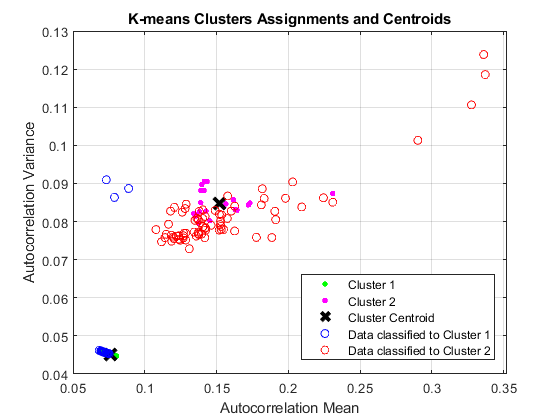

hold on
[~,idx_test] = pdist2(C,Xtest,'euclidean','Smallest',1);
gscatter(Xtest(:,1),Xtest(:,2),idx_test,'bry','ooo')
gscatter(Xtest(:,1),Xtest(:,2),idx_test,'bry','ooo')
legend('Cluster 1','Cluster 2','Cluster Centroid', ...
  'Data classified to Cluster 1','Data classified to Cluster 2')
hold off

To calcule the accuracy of the *k*-Means method, we'll compare the cluster that the data are fitted with the actual labels. 

As said before the first 80 data coordinates (means and variance) in the matrix Xtest are from data with signal (FM 88.9 and FM 93.9), and the last 20 are from noise. As we see in the plots above, the noise data are classified by cluster centroid 1, and the signal samples by cluster centroid 2. So lets create a vector with the labels:

labels(1, 1:80) = 2;
labels(1, 81:100) = 1

labels =      2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


And so we now can take the accuracy of the method by compare the classified data with theirs label.

accuracy = sum(labels == idx_test)/length(labels)

accuracy = 0.9700

We can also calculate the accuracy of the each signal.

accuracyFM88 = sum(labels(1:40) == idx_test((1:40)))/length(labels(1:40))

accuracyFM88 = 0.9250

accuracyFM93 = sum(labels(41:80) == idx_test((41:80)))/length(labels(41:80))

accuracyFM93 = 1

accuracyNoise = sum(labels(81:100) == idx_test((81:100)))/length(labels(81:100))

accuracyNoise = 1

Looking at these results you can clairly see that the *k*-Means method could detect and differentiate signal from the noise by calculating the mean and variance of the autocorrelation. We can se by the graphs that the noise signals stays close to the origin as compared with samples with some signal. And from the accuracy we can see that the model can detect signals from other frequencies that aren't used for training.

## Ploting the clusters region

We can also use *k*-`Means` to compute the distance from each centroid to points on a grid.

x1 = min(Xtest(:,1)- 0.02):0.0001:max(Xtest(:,1) + 0.02);
x2 = min(Xtest(:,2)- 0.01):0.0001:max(Xtest(:,2) + 0.01);
[x1G,x2G] = meshgrid(x1,x2);
XGrid = [x1G(:),x2G(:)]; % Defines a fine grid on the plot

idx2Region = kmeans(XGrid,2,'MaxIter',1,'Start',C);

k-means will displays a warning stating that the algorithm did not converge, which you should expect since the software only implemented one iteration.

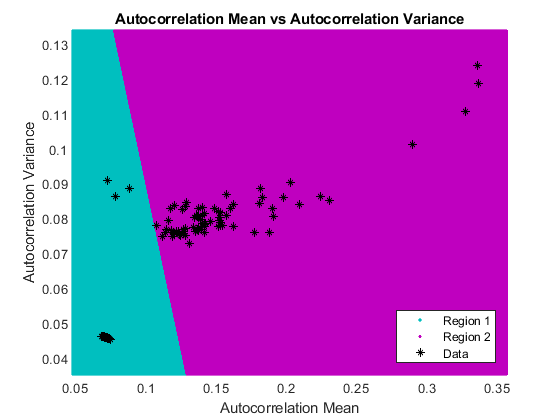

figure;
gscatter(XGrid(:,1),XGrid(:,2),idx2Region,...
    [0,0.75,0.75;0.75,0,0.75;0.75,0.75,0],'..');
hold on;
plot(Xtest(:,1),Xtest(:,2),'k*','MarkerSize',5);
title 'Autocorrelation Mean vs Autocorrelation Variance';
xlabel 'Autocorrelation Mean';
ylabel 'Autocorrelation Variance'; 
legend('Region 1','Region 2','Data','Location','SouthEast');
xlim([min(x1), max(x1)])
ylim([min(x2), max(x2)])
hold off;